a = 1+mod(163,3)

a = 2

Problem1

SubProblem1

Fs = 120;
t = 0:1/Fs:2;
y = sin(2*pi*15*a*t);
Y = fft(y,120);
N = length(Y)

N = 120

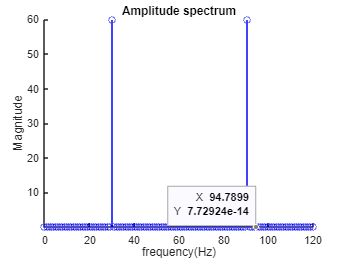

f = (0:Fs/(N-1):Fs);
figure
hold on
stem(f(1:120),abs(Y),'b')
title("Amplitude spectrum")
xlabel("frequency(Hz)")
ylabel("Magnitude")

Problem1 

Subproblem 2

n = 130

n = 130

Y1 = fft(y,n);
N = length(Y1)

N = 130

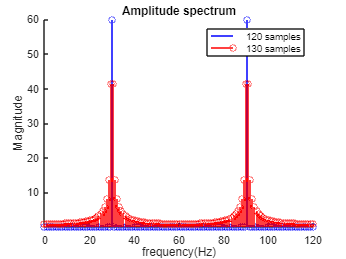

f = (0:Fs/(N-1):Fs);
stem(f(1:n),abs(Y1),'r')
legend("120 samples","130 samples")
hold off

Problem 1

Subproblem 3

for i = 40:40:240 
    Yn = fft(y,i);
    N = length(Yn)
    f = (0:Fs/(N-1):Fs);
    hold on
    stem(f,abs(Yn))
    title("Amplitude spectrum")
    hold off
end

N = 40

N = 80

N = 120

N = 160

N = 200

N = 240

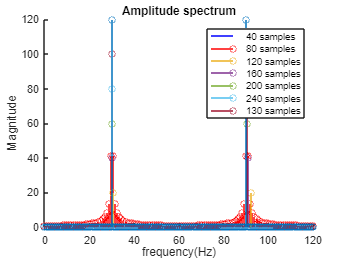

legend("40 samples","80 samples","120 samples","160 samples","200 samples","240 samples","130 samples")

Problem 2

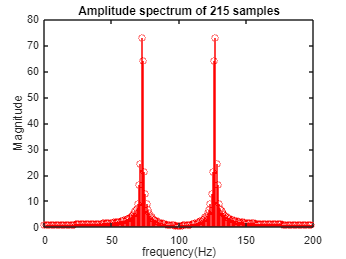

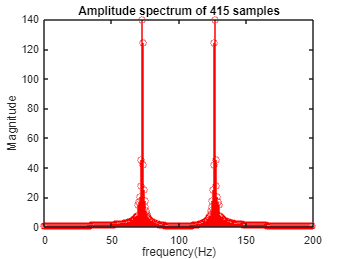

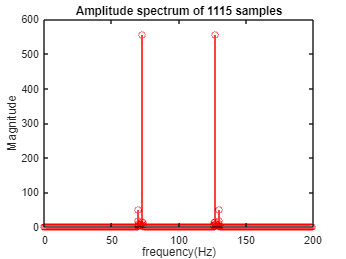

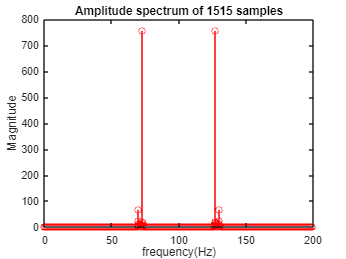

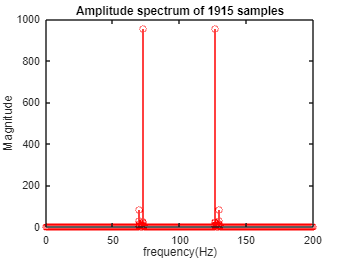

Fs = 200;
t = 0:1/Fs:10;
A = 140;
B = 146;
xa = 0.1*sin(A*pi*t) + cos(B*pi*t);
f = (0:Fs/(length(xa)-1):Fs)*10;
n = [215 415 1115 1515 1915];
for i = n
    figure
    Z = fft(xa,i);
    stem(200*f(1:i)/i,abs(Z),'r')
    title("Amplitude spectrum of " + i + " samples")
    xlabel("frequency(Hz)")
    ylabel("Magnitude")
end

Problem 3

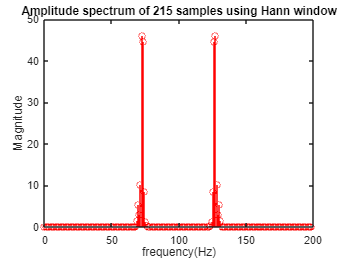

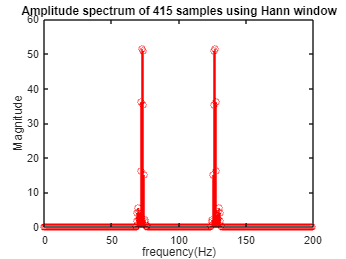

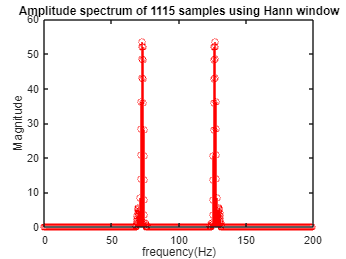

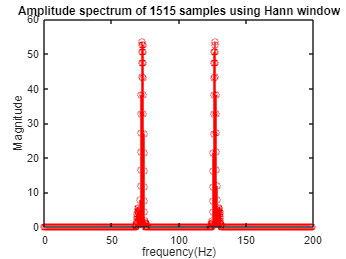

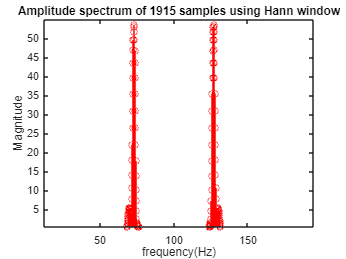

for i = n
    figure
    xan = xa(1:215).*(hann(215))';
    Z = fft(xan,i);
    stem(200*f(1:i)/i,abs(Z),'r')
    title("Amplitude spectrum of " + i + " samples using Hann window")
    xlabel("frequency(Hz)")
    ylabel("Magnitude")
end

Problem4

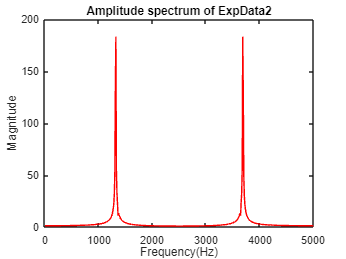

load Exp4Data2.txt
z = Exp4Data2;
Z = fft(z);
Fs = 5000;
f= 0:Fs/(length(z)-1):Fs;
plot(f,abs(Z),'r')
title("Amplitude spectrum of ExpData2")
xlabel("Frequency(Hz)")
ylabel("Magnitude")

[maxm,value] = max(abs(Z));
fund_freq = f(value)

fund_freq = 1.3226e+03

factor = [f(value) ; Fs - f(value)]/Fs;

Problem4

SubProblem 1

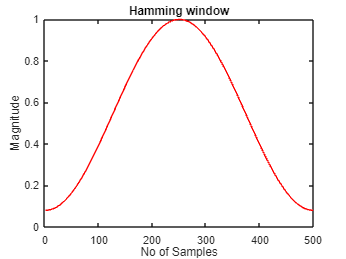

h = hamming(500);
plot(h,'r')
title("Hamming window")
xlabel("No of Samples")
ylabel("Magnitude")


z1 = z.*(h)';
Z = fft(z1,10000);
Fs = 5000

Fs = 5000

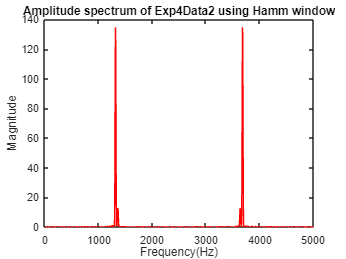

f= 0:Fs/(length(Z)-1):Fs;
plot(f,abs(Z),'r')
title("Amplitude spectrum of Exp4Data2 using Hamm window")
xlabel("Frequency(Hz)")
ylabel("Magnitude")

[value,idx] = max(abs(Z));
fund_freq = f(idx)

fund_freq = 1.3161e+03

factor = [f(idx) ; Fs - f(idx)]/Fs;

Problem4

SubProblem 2

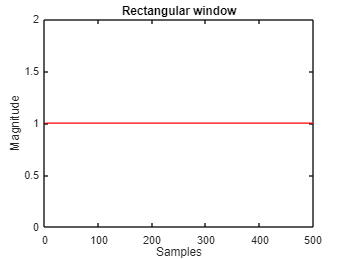

h = rectwin(500);
plot(h,'r')
title("Rectangular window")
xlabel("Samples")
ylabel("Magnitude")

z1 = z.*(h)';
Z = fft(z1,10000);
Fs = 5000

Fs = 5000

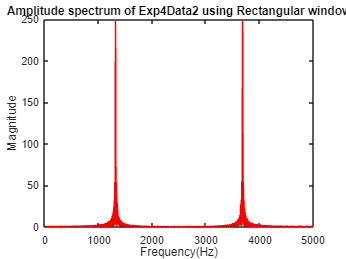

f= 0:Fs/(length(Z)-1):Fs;
plot(f,abs(Z),'r')
title("Amplitude spectrum of Exp4Data2 using Rectangular window")
xlabel("Frequency(Hz)")
ylabel("Magnitude")

[value,idx] = max(abs(Z));
fund_freq = f(idx)

fund_freq = 1.3161e+03

factor = [f(idx) ; Fs - f(idx)]/Fs;